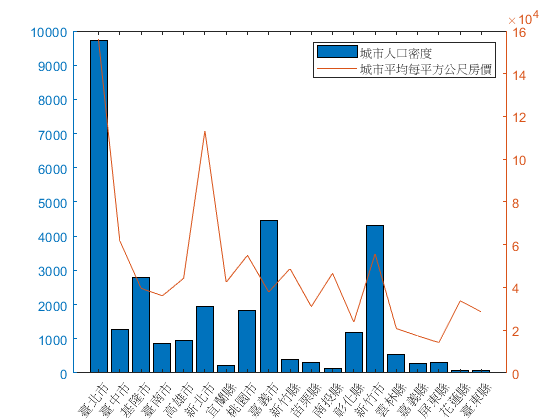

clear;clc;
warning('off');
% echo off;
%override default ProgressReporter (normally a CommandWindowProgressReporter) with a NullProgressReporter which displays nothing
% matlab.bigdata.internal.executor.ProgressReporter.override(matlab.bigdata.internal.executor.NullProgressReporter);

file_names = ["a_lvr_land_a.csv", "b_lvr_land_a.csv", "c_lvr_land_a.csv", "d_lvr_land_a.csv", "e_lvr_land_a.csv", "f_lvr_land_a.csv", "g_lvr_land_a.csv", "h_lvr_land_a.csv", "i_lvr_land_a.csv", "j_lvr_land_a.csv", "k_lvr_land_a.csv", "m_lvr_land_a.csv", "n_lvr_land_a.csv", "o_lvr_land_a.csv", "p_lvr_land_a.csv", "q_lvr_land_a.csv", "t_lvr_land_a.csv", "u_lvr_land_a.csv", "v_lvr_land_a.csv"];

price_tables = {};

names = {'village','ransaction_sign','location','land_area','using_method','non-metropolis','non-metropolis-use','date','transaction_number','floor','total_floor','state','main_use','materials','complete_years','building_area','rooms','halls','healths','compartmenteds','manage','total_price','unit_price','berth_type','berth_area','berth_price','note','serial_number'};

for i = 1:length(file_names)
    price_tables{end + 1} = getCsvTable("lvr_landAcsv/" + file_names(i), names);
end

popularity = getCsvTable('opendata108N010.csv');

keyset = {'a','b','c','d','e','f','g','h','i','j','k','m','n','o','p','q','t','u','v'};
valueset = {'臺北市','臺中市','基隆市','臺南市','高雄市','新北市','宜蘭縣','桃園市','嘉義市','新竹縣','苗栗縣','南投縣','彰化縣','新竹市','雲林縣','嘉義縣','屏東縣','花蓮縣','臺東縣'};

map = containers.Map(keyset, valueset);

city_popularity_density = zeros(1, length(keyset));

for i = 1:length(keyset)
    village = cellfun(@(x)regexp(x,['^' map(keyset{i})]),popularity.site_id,'UniformOutput',false);
    
    index_village = cell2mat(cellfun(@(x) cmp(x, 1), village, 'un', 0));
    
    village_cols = popularity(index_village, :);
    
    city_popularity_density(i) = sum(village_cols.people_total) / sum(village_cols.area);
end

unit_price_mean = zeros(1, length(price_tables));

for i = 1:length(price_tables)
    unit_price_mean(i) = sum(price_tables{i}.unit_price) / sum(price_tables{i}.unit_price > 1000);
end

yyaxis left;
bar(city_popularity_density);

yyaxis right;
plot(unit_price_mean);

xticks(1:1:length(valueset));
xticklabels(valueset);
set(gca, 'XTickLabelRotation', 50);

legend("城市人口密度", "城市平均每平方公尺房價");


keyset_6 = {'a','b','d','e','f','h'};
valueset_6 = {1, 2, 4, 5, 6, 8};

map_index = containers.Map(keyset_6, valueset_6);

villages = cell(1, length(price_tables));

villages_6 = {{'文山區','中正區','萬華區','大同區','內湖區','松山區','信義區','南港區','大安區'}, {'南區','西區','中區','北區','北屯區','南屯區','西屯區','后里區','豐原區','神岡區','大甲區','梧棲區','新社區','石岡區','和平區','大雅區','潭子區','霧峰區','烏日區','大里區','太平區','大肚區','龍井區','東勢區'}, {'中西區','安平區','北區','安南區','南區','東區','新營區','白河區','官田區','麻豆區','七股區','佳里區','西港區','學甲區','將軍區','安定區','善化區','新市區','新化區','仁德區','關廟區','歸仁區','玉井區','永康區','柳營區','六甲區','龍崎區'}, {'前金區','鼓山區','鹽埕區','新興區','苓雅區','小港區','前鎮區','三民區','楠梓區','左營區','岡山區','橋頭區','鳳山區','甲仙區','旗山區','仁武區','大社區','鳥松區','阿蓮區','湖內區','六龜區','大寮區','林園區'}, {'板橋區','土城區','新莊區','泰山區','林口區','新店區','深坑區','坪林區','汐止區','淡水區','瑞芳區','三重區','蘆洲區','中和區','永和區','鶯歌區','三峽區','樹林區','平溪區'}, {'楊梅區','蘆竹區','八德區','平鎮區','龜山區','桃園區','中壢區','平鎮區','復興區','龍潭區','大溪區'}};

villages_density = zeros(length(price_tables), 30);

for i = 1:length(price_tables)
    villages_now = price_tables{i}.village;
    
    villages_now = unique(villages_now);
    
    villages{i} = villages_now;
end

keyset_lost = {};
valueset_lost = {};

for i = 1:length(price_tables)
    for j = 1:length(villages{i})
        village = cellfun(@(x)regexp(x,['^' map(keyset{i}) villages{i}{j}]),popularity.site_id,'UniformOutput',false);
        
        index_village = cell2mat(cellfun(@(x) cmp(x, 1), village, 'un', 0));
        
        village_cols = popularity(index_village, :);
        
        try
            villages_density(i, j) = village_cols.population_density;
        catch ME
            ['lost data on ' map(keyset{i}) villages{i}{j}]
            
            keyset_lost{end + 1} = map(keyset{i});
            valueset_lost{end + 1} = villages{i}{j};
        end
    end
end

ans = 'lost data on 嘉義市嘉義市'

ans = 'lost data on 苗栗縣頭份巿'

ans = 'lost data on 新竹市新竹市'

ans = 'lost data on 雲林縣台西鄉'

ans = 'lost data on 屏東縣屏東巿'

ans = 'lost data on 臺東縣台東市'


map_lost = containers.Map(keyset_lost, valueset_lost);

villages_price = zeros(length(price_tables), 30);

for i = 1:length(price_tables)
    for j = 1:length(villages{i})
        village = cellfun(@(x)regexp(x,['^' villages{i}{j}]),price_tables{i}.village,'UniformOutput',false);
        
        index_village = cell2mat(cellfun(@(x) cmp(x, 1), village, 'un', 0));
        
        village_cols = price_tables{i}(index_village, :);
        
        if(isinf(sum(village_cols.unit_price) / sum(village_cols.unit_price > 1000)))
            ['no trade data on ' map(keyset{i}) villages{i}{j}]
        else
            villages_price(i, j) = sum(village_cols.unit_price) / sum(village_cols.unit_price > 1000);
        end
    end
    
end

ans = 'no trade data on 臺中市和平區'

ans = 'no trade data on 臺南市將軍區'

ans = 'no trade data on 臺南市關廟區'

ans = 'no trade data on 臺南市龍崎區'

ans = 'no trade data on 新北市坪林區'

ans = 'no trade data on 新北市平溪區'

ans = 'no trade data on 桃園市復興區'

ans = 'no trade data on 新竹縣北埔鄉'

ans = 'no trade data on 苗栗縣泰安鄉'

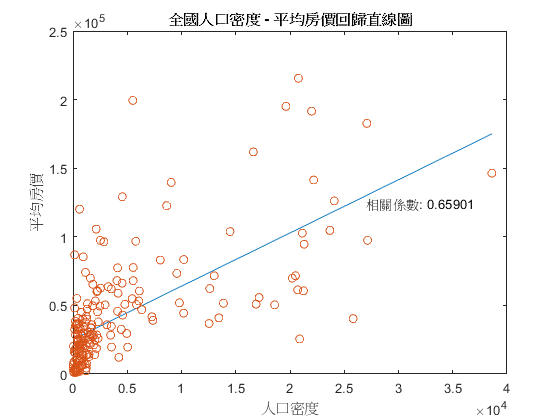


x = [];
y = [];

for i = 1:length(price_tables)
    for j = 1:30
        if(villages_density(i, j) ~= 0 && villages_price(i, j) ~= 0)
            x = [x villages_density(i, j)];
            y = [y villages_price(i, j)];
        end
    end
end

the_line = polyfit(x, y, 1);

figure

plot(linspace(0, max(villages_density(:)), 10), polyval(the_line, linspace(0, max(villages_density(:)), 10)));

hold on

plot(x, y, 'o');

title("全國人口密度 - 平均房價回歸直線圖")

xlabel("人口密度");
ylabel("平均房價");

r = the_line(1) * std(x) / std(y);

text(27000, 125000, ['相關係數: ', num2str(r)]);

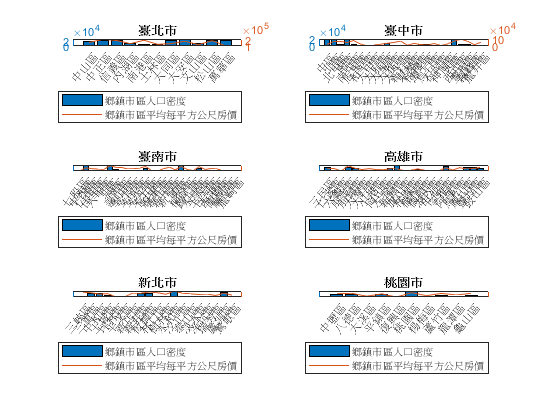


for i = 1:6
    subplot(3,2,i);
        
    yyaxis left;
    bar(villages_density(valueset_6{i}, 1:length(villages{valueset_6{i}})));
    
    yyaxis right;
    plot(villages_price(valueset_6{i},1:length(villages{valueset_6{i}})))
    
    title(valueset(map_index(keyset_6{i})));
    
    xticks(1:1:length(villages{valueset_6{i}}));
    xticklabels(villages{valueset_6{i}});
    set(gca, 'XTickLabelRotation', 50);
    
    
    legend("鄉鎮市區人口密度", "鄉鎮市區平均每平方公尺房價", 'location', 'southoutside');
end